clc
clear all
close all
rng(0)
save_run = true;

# M3C Simulation

## Parameters

Simulation and control steps

Tf = 0.2;       % Total simulation time
Ts = 100e-6;    % Sampling time
Ns = Tf/Ts      % Number of sampling steps

Ns = 2000

Ti = 10e-6;	    % Integration step
Ni = Ts/Ti      % Number of integration steps between each ISR (Interrupt Service Routine)

Ni = 10

Tsim = linspace(0, Tf, Ni);

% Sampling


%% PLL

% %% Total energy balance
% Ti = 1e-4;                     % Sample time
% Ni = round(Tf/Ti + 1);         % Number of steps
% Tcur = linspace(0, Tf, Ni);
% %% ICB + LFOM
% Tl = 1e-4;                   % Sample time
% Nl = round(Tf/Tl + 1);       % Number of steps
% Ten = linspace(0, Tf, Nl);

## External system

Input

Ax0 = 7000;
fx0 = 50;
wx0 = 2*pi*fx0;

Output

Ay0 = 5000;
fy0 = 50;
wy0 = 2*pi*fy0;

## Modular Multilevel Matrix Converter

M3C

specsM3C = struct();

% Constants
specsM3C.Constants.Ti  = 1e-5;     % Integration step
specsM3C.Constants.R   = 1e-3;     % Branch resistance
specsM3C.Constants.L   = 20e-3;    % Branch inductance
specsM3C.Constants.Csm = 20e-3;    % Submodule capacitance
specsM3C.Constants.Nsm = 4;        % Submodules per cluster

% Initial Values
specsM3C.InitialValues.is = zeros(9, 1);                    % Cluster current
specsM3C.InitialValues.vc = 1.5 * (Ax0 + Ay0) * ones(9, 1); % Cluster capacitor voltage

M3C = ClassM3C(specsM3C)

M3C =   ClassM3C with properties:

        A: [6×9 double]
    pinvA: [9×6 double]
        m: 9
        N: [9×4 double]
        n: 4
    pinvN: [4×9 double]
       Ti: 1.0000e-05
        R: 1.0000e-03
        L: 0.0200
      Csm: 0.0200
      Nsm: 4
        C: 0.0050
       Ad: [9×9 double]
       Bd: [9×9 double]
      ixy: [6×1 double]
       is: [9×1 double]
       iB: [9×1 double]
       iz: [9×1 double]
       ie: [4×1 double]
       vc: [9×1 double]
       Ec: [9×1 double]


## Phase Locked Loop

Input and output PLL

specsPLL.Ts = 100e-6;
specsPLL.kp = 0.5;
specsPLL.ki = 1.5;

PLLx = ClassPLL(specsPLL)

PLLx =   ClassPLL with properties:

    Ts: 1.0000e-04
    kp: 0.5000
    ki: 1.5000
     n: 0.9999
     e: 0
     a: 0
     u: 0
     w: 0
     g: 0


PLLy = ClassPLL(specsPLL)

PLLy =   ClassPLL with properties:

    Ts: 1.0000e-04
    kp: 0.5000
    ki: 1.5000
     n: 0.9999
     e: 0
     a: 0
     u: 0
     w: 0
     g: 0


## Low Pass Mean Energy Filter

LPF

specsLPF = struct();
specsLPF.Ts = 100e-6;
specsLPF.wn = 2*pi*5; % Hand tuned
specsLPF.y0 = mean(M3C.Ec);

LPF = ClassLPF(specsLPF)

LPF =   ClassLPF with properties:

        Ts: 1.0000e-04
        wn: 31.4159
        b0: 0.0031
        b1: 0.0031
        a0: -1.9969
        a1: 2.0031
       y_t: 810000
     y_t_1: 810000
      yf_t: 810000
    yf_t_1: 810000


## Total Energy Balance Proportional Integral Controller

PI

Ix_max = 200; % Maximum input current

specsPI.Ts = 100e-6;
% Hand tuning (First wn_filt with kp_pi, then ki_pi)
specsPI.kp = 0.1;
specsPI.ki = 5;
specsPI.u_min = -Ix_max;
specsPI.u_max = Ix_max;

PI = ClassPI(specsPI)

PI =   ClassPI with properties:

       Ts: 1.0000e-04
       kp: 0.1000
       ki: 5
        n: 0.9975
    u_min: -200
    u_max: 200
        e: 0
        a: 0
        u: 0



% % (Mean energy)/(Input current) transfer function
% k_teb = Ax/(6*vc_ref) * Nsm/Csm
% G_teb = k_teb*tf([1], [1, 0])

% %%% SEPARATED PI controller and feedback filter design
% % Pole assignment
% % Second order pole
% xi_acl = 0.08;                   % Damping factor
% wn_acl = 2*pi*1.29;              % Natural frequency
% 
% % PI
% kp_pi = 2*xi_acl*wn_acl/k_teb % Proportional gain
% ki_pi = wn_acl^2/k_teb        % Integrator gain
% % Filter
% wn_filt = 2*pi*5              % Natural frequency

% %%% JOINT PI controller and feedback filter design
% % Pole assignment (three first order)
% % First order pole
% wn_acl = 2*pi*0.5;        % Natural frequency
% 
% % PI
% kp_pi = wn_acl/k_teb
% ki_pi = wn_acl^2/(3*k_teb)
% % Filter
% wn_filt = 3*wn_acl

% %%% JOINT PI controller and feedback filter design
% % Pole assignment (one second order + one first order)
% % Second order pole
% xi_acl = 0.01;              % Damping factor
% wn_acl = 2*pi*1.3;           % Natural frequency
% % First order pole
% alpha_acl = 2*pi*5;        % Natural frequency
% 
% % PI
% kp_pi = wn_acl*(wn_acl+2*xi_acl*alpha_acl)/(k_teb*(2*wn_acl*xi_acl+alpha_acl))
% ki_pi = wn_acl^2*alpha_acl/(k_teb*(2*wn_acl*xi_acl+alpha_acl))
% % Filter
% wn_filt = 2*wn_acl*xi_acl+alpha_acl

## Cluster Energy Model Predictive Controller

CEMPC

specsM3C.Constants.Ti = 100e-6;

specsCEMPC.M3C = ClassM3C(specsM3C);
specsCEMPC.is_max = 250;
specsCEMPC.vo_max = (Ax0 + Ay0)/2;
specsCEMPC.Ts = 100e-6;
specsCEMPC.lambda_z = 2;
specsCEMPC.lambda_o = 0.1;
specsCEMPC.lmax = 10;
specsCEMPC.Np = 1;

CEMPC = ClassCEMPC(specsCEMPC)

CEMPC =   ClassCEMPC with properties:

           M3C: [1×1 ClassM3C]
        is_max: 250
        vo_max: 6000
            Ts: 1.0000e-04
      lambda_z: 2
      lambda_o: 0.1000
          lmax: 10
            Np: 1
            NN: [9×4 double]
     options_i: [1×1 mpcActiveSetOptions]
     options_v: [1×1 mpcActiveSetOptions]
        ie_ref: [4×1 double]
        iz_ref: [9×1 double]
        vo_ref: 0
           iAi: [18×1 logical]
           iAv: [2×1 logical]
    exitflag_i: -9999
    exitflag_v: -9999


## Cluster Current Model Predictive Controller

CCMPC

specsM3C.Constants.Ti = 100e-6;
CCMPC = ClassCCMPC(M3C)

CCMPC =   ClassCCMPC with properties:

         M3C: [1×1 ClassM3C]
      lambda: 5.0000e-05
     options: [1×1 mpcActiveSetOptions]
          iA: [18×1 logical]
          vs: [9×1 double]
    exitflag: -9999


## Utils

abc to dq frame of reference

Tabc2dq = @(g) (2/3)*[cos(g), cos(g-2*pi/3), cos(g+2*pi/3); -sin(g), -sin(g-2*pi/3), -sin(g+2*pi/3)];

alpha beta to abc frame of reference and vice versa

Tabc2ab = (2/3)*[1, -1/2, -1/2; 0, sqrt(3)/2, -sqrt(3)/2];
Tab2abc = [1, 0; -1/2, sqrt(3)/2; -1/2, -sqrt(3)/2];

Rotation matrices

% Counter clockwise rotation matrix
rot = @(theta) [cos(theta), -sin(theta);
                sin(theta),  cos(theta)];

% Input
theta = wx0 * Ts;
angles = (0:specsCEMPC.Np-1) * theta;
cos_vals = cos(angles);
sin_vals = sin(angles);
ROTx = reshape([cos_vals; -sin_vals; sin_vals; cos_vals], 2, 2*specsCEMPC.Np)';

% Output
theta = wy0 * Ts;
angles = (0:specsCEMPC.Np-1) * theta;
cos_vals = cos(angles);
sin_vals = sin(angles);
ROTy = reshape([cos_vals; -sin_vals; sin_vals; cos_vals], 2, 2*specsCEMPC.Np)';

% DISCLAIMER: This rotation matrices produce a vector of Np steps starting
% from now, so it actually only predicts Np-1 steps. This has to be taken in
% account in case of control delay compensation.

# Simulation

Buffer

buffer = struct();
buffer.is = zeros(M3C.m, Ns);
buffer.ixy = zeros(size(M3C.A, 1), Ns);
buffer.iB = zeros(M3C.m, Ns);
buffer.iz = zeros(M3C.m, Ns);
buffer.ie = zeros(M3C.n, Ns);
buffer.vs = zeros(M3C.m, Ns);
buffer.vxy = zeros(size(M3C.A, 1), Ns);
buffer.vB = zeros(M3C.m, Ns);
buffer.vo = zeros(1, Ns);
buffer.Ec = zeros(M3C.m, Ns);
buffer.vc = zeros(M3C.m, Ns);
buffer.Ec_mean = zeros(1, Ns);
buffer.Ec_mean_filt = zeros(1, Ns);

Initialize

Ax = Ax0;
Ay = Ay0;
wx = wx0;
wy = wy0;
gx = 0;
gy = 0;

vc_mean_ref = 1.5 * (Ax + Ay);
Ec_mean_ref = M3C.C/2 * vc_mean_ref^2;

vc_ref = vc_mean_ref * ones(9, 1);
Ec_ref = Ec_mean_ref * ones(9, 1);

Run

for ts = 1:Ns

%% Measure external voltages
vxa = Ax * cos(gx);
vxb = Ax * cos(gx-2*pi/3);
vxc = Ax * cos(gx+2*pi/3);
vyr = Ay * cos(gy);
vys = Ay * cos(gy-2*pi/3);
vyt = Ay * cos(gy+2*pi/3);
vxy = [vxa; vxb; vxc; vyr; vys; vyt];
vB = M3C.A' * vxy;

%% Input PLL
vxdq = Tabc2dq(PLLx.g) * vxy(1:3);
PLLx = PLLx.step(vxdq);

%% Output PLL
vydq = Tabc2dq(PLLy.g) * vxy(4:6);
PLLy = PLLy.step(vydq);

%% "Measure" converter cluster mean voltage
Ec = M3C.Ec;
Ec_mean = mean(Ec);

%% Low pass filter for mean cluster energy
LPF = LPF.filter(Ec_mean);
Ec_mean_filt = LPF.yf_t;
Ec_mean_filt = Ec_mean;

%% Calculate input currents references (TEB PI)
% dq
PI = PI.step(Ec_mean_ref, Ec_mean_filt);
ixd_ref = PI.u;
ixq_ref = 0;
% abc
ixa_ref = ixd_ref * cos(PLLx.g)          - ixq_ref * sin(PLLx.g);
ixb_ref = ixd_ref * cos(PLLx.g - 2*pi/3) - ixq_ref * sin(PLLx.g - 2*pi/3);
ixc_ref = ixd_ref * cos(PLLx.g + 2*pi/3) - ixq_ref * sin(PLLx.g + 2*pi/3);

%% Calculate input currents references (Converter application)
% dq
iyd_ref = 100;
iyq_ref = 0;
% abc
iyr_ref = iyd_ref * cos(PLLy.g)          - iyq_ref * sin(PLLy.g);
iys_ref = iyd_ref * cos(PLLy.g - 2*pi/3) - iyq_ref * sin(PLLy.g - 2*pi/3);
iyt_ref = iyd_ref * cos(PLLy.g + 2*pi/3) - iyq_ref * sin(PLLy.g + 2*pi/3);

%% Concatenate external currents references
ixy_ref = [ixa_ref; ixb_ref; ixc_ref; iyr_ref; iys_ref; iyt_ref];

%% Basic currents references
iB_ref = M3C.pinvA * ixy_ref;

%% Predict external voltages/currents
vB_pred = predict_basic_assuming_symmetrical(vxy, specsCEMPC.Np, ROTx, ROTy, Tabc2ab, Tab2abc, M3C.pinvA);
iB_pred = predict_basic_assuming_symmetrical(M3C.ixy, specsCEMPC.Np, ROTx, ROTy, Tabc2ab, Tab2abc, M3C.pinvA);

%% TEB MPC
CEMPC = CEMPC.control(M3C.Ec, vB_pred, iB_pred);

%% CC MPC
is_ref = CEMPC.iz_ref + iB_ref;
CCMPC = CCMPC.control(is_ref, vc_mean_ref, M3C.is, vB, CEMPC.vo_ref);

%% Store variables
buffer.is(:, ts) = M3C.is;
buffer.ixy(:, ts) = M3C.ixy;
buffer.iB(:, ts) = M3C.iB;
buffer.iz(:, ts) = M3C.iz;
buffer.ie(:, ts) = M3C.ie;
buffer.vs(:, ts) = CCMPC.vs;
buffer.vxy(:, ts) = vxy;
buffer.vB(:, ts) = vB;
buffer.vo(:, ts) = CEMPC.vo_ref;
buffer.Ec(:, ts) = M3C.Ec;
buffer.vc(:, ts) = M3C.vc;
buffer.Ec_mean(ts) = Ec_mean;
buffer.Ec_mean_filt(ts) = Ec_mean_filt;

%% Integrate external system and converter
for ti = 1:Ni
    % Update model
    M3C = M3C.step(CCMPC.vs, vxy, CEMPC.vo_ref);
    
    % Update external system
    
    gx = gx + wx * Ti;
    gy = gy + wy * Ti;
    vxa = Ax * cos(gx);
    vxb = Ax * cos(gx-2*pi/3);
    vxc = Ax * cos(gx+2*pi/3);
    vyr = Ay * cos(gy);
    vys = Ay * cos(gy-2*pi/3);
    vyt = Ay * cos(gy+2*pi/3);
    vxy = [vxa; vxb; vxc; vyr; vys; vyt];
end

end

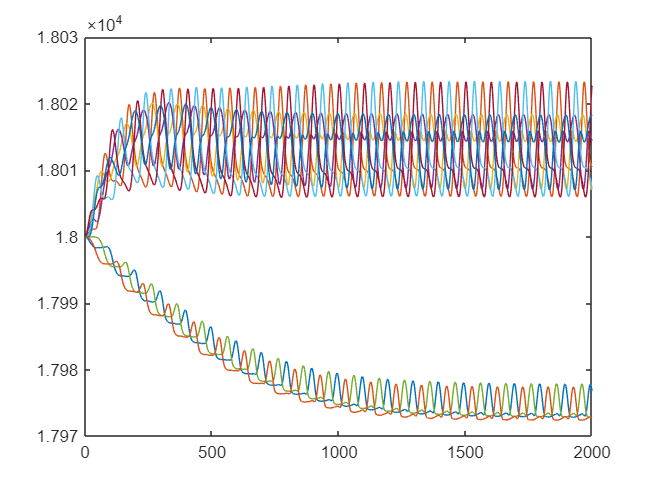

plot(buffer.vc')

Maneuver (just output frequency variation for the beta version. the control must be validated with variation of references and disturbances)

% Tini = 0.2;                   % Initial time
% Tfin = 0.3;                   % Final time
% fyf = 50;                     % Final frequency
% wyf = fyf*2*pi;               % Final speed
% acel = (wyf-wy0)/(Tfin-Tini); % Acceleration
% 
% isManeuver = (Tini < Tsim) & (Tsim < Tfin);
% isManeuver = [isManeuver, isManeuver(end)*ones(1, Np)];
% accelVector = acel * isManeuver;
% wy = wy0 + Ts*cumsum(accelVector);
% wx = wx0 *ones(1, Ns+Np);
% 
% % Timeseries
% gx = Ts*cumsum(wx);
% gy = Ts*cumsum(wy);
% vxa = Ax*cos(gx);
% vxb = Ax*cos(gx-2*pi/3);
% vxc = Ax*cos(gx+2*pi/3);
% vyr = Ay*cos(gy);
% vys = Ay*cos(gy-2*pi/3);
% vyt = Ay*cos(gy+2*pi/3);
% 
% vxy = [vxa; vxb; vxc; vyr; vys; vyt];
% vB = A'*vxy;

## Simulation

Reference frame transformations

% Tab_abc = (2/3)*[1, -1/2, -1/2; 0, sqrt(3)/2, -sqrt(3)/2];
% Tabc_ab = [1, 0; -1/2, sqrt(3)/2; -1/2, -sqrt(3)/2];
% 
% Tabc_dq_function = @(g) (2/3)*[cos(g),  cos(g-2*pi/3),  cos(g+2*pi/3);
%                               -sin(g), -sin(g-2*pi/3), -sin(g+2*pi/3)];

For projection of voltages and currents

% % Counter clockwise rotation matrix
% rot = @(theta) [cos(theta), -sin(theta);
%                 sin(theta),  cos(theta)];
% 
% % Input
% theta = wx0 * Tl;
% angles = (0:Np-1) * theta;
% cos_vals = cos(angles);
% sin_vals = sin(angles);
% ROTx = reshape([cos_vals; -sin_vals; sin_vals; cos_vals], 2, 2*Np)';
% 
% % Output
% theta = wy0 * Tl;
% angles = (0:Np-1) * theta;
% cos_vals = cos(angles);
% sin_vals = sin(angles);
% ROTy = reshape([cos_vals; -sin_vals; sin_vals; cos_vals], 2, 2*Np)';
% 
% % Null matrix for future currents
% NN = repmat({N}, Np, 1);
% NN = blkdiag(NN{:});

Limit values

% Vxy_max = Ax+Ay;     % Branch voltage
% Von_max = Vxy_max/2; % Common mode voltage
% Is_max = 250;        % Cluster current
% Ix_max = 200;        % Input current

Constant references

% %% Cluster capacitor voltage reference
% vc_ref = 1.5*Vxy_max;
% %% Cluster capacitor energy reference
% Ec_ref = 0.5*vc_ref^2*Csm/Nsm;

Control parameters and initialization

- TEB

% % Initialization
% [a_teb, u_teb, e_teb] = deal(0);
% [Ixd_ref, Ixq_ref] = deal(zeros(1, Ns));
% [ixa_ref, ixb_ref, ixc_ref, iyr_ref, iys_ref, iyt_ref] = deal(zeros(1, Ns));
% ixy_ref = zeros(6, Ns);
% iB_ref = zeros(m, Ns);
% 
% %% dq output current reference (this must come from the converter's application)
% % Iy_dref = 10*ones(1, Ns); % Iyd_ref(t) = 200; -> Maneuver
% % Iy_qref = 60*ones(1, Ns);
% Iyd_ref = 100*ones(1, Ns);
% % Iyd_ref(round(Ns/2):end) = 200;
% Iyq_ref = 0*ones(1, Ns);

- ICB + LFOM

% % Parameters
% lambda_z = 2;
% lambda_o = 0.1;

- Cluster current control

% % Parameters
% lambda = 0.00005;

Initialization

% ixy = deal(zeros(6, Ns));
% iB = deal(zeros(m, Ns));
% [is, Ec] = deal(zeros(m, Ns+1));
% rng(0)
% vc0 = vc_ref*ones(m, 1); % Cluster capacitor voltage
% Ec0 = (Csm/Nsm/2)*vc0.^2; % Cluster energy
% Ec(:, 1) = Ec0;
% [Ec_mean, Ec_mean_filt] = deal(zeros(1, Ns));
% [Ec_mean(1), Ec_mean_filt(1)] = deal(Ec_ref);

Run

% for t = 1:length(Tsim)
%     % Mean energy
%     Ec_mean(t) = mean(Ec(:, t));
%     if t > 1
%     Ec_mean_filt(t) = (-a0_filt*Ec_mean_filt(t-1) + b1_filt*Ec_mean(t) + b0_filt*Ec_mean(t-1))/a1_filt;
%     end
% 
%     % External and basic currents
%     ixy(:, t) = A*is(:, t);
%     iB(:, t) = pinvA*ixy(:, t);
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % TEB control
%     if any(Tcur==Tsim(t))
%         % TEB PI
%         e_teb_prev = e_teb; % Previous error
%         % e_teb = (vc_ref-sqrt(2*Nsm/Csm*abs(Ec_mean_filt(t)))*sign(Ec_mean_filt(t))); % Actual error
%         e_teb = Ec_ref-Ec_mean_filt(t); % Actual error
%         u_teb = u_teb + (kp_pi+ki_pi*Ti/2)*e_teb + (-kp_pi+ki_pi*Ti/2)*e_teb_prev; % Control action (Tustin)
%         % u_teb = u_teb + kp*e_teb + (Ti*ki-kp)*e_teb_prev; % Control action (Backward Euler)
%         u_teb = clip(u_teb, -Ix_max, Ix_max); % Saturation between Ix_max*[-1, 1]
% 
%         Ixd_ref(t) = u_teb;
%         ixa_ref(t) = Ixd_ref(t)*cos(gx(t))        - Ixq_ref(t)*sin(gx(t));
%         ixb_ref(t) = Ixd_ref(t)*cos(gx(t)-2*pi/3) - Ixq_ref(t)*sin(gx(t)-2*pi/3);
%         ixc_ref(t) = Ixd_ref(t)*cos(gx(t)+2*pi/3) - Ixq_ref(t)*sin(gx(t)+2*pi/3);
% 
%         iyr_ref(t) = Iyd_ref(t)*cos(gy(t))        - Iyq_ref(t)*sin(gy(t));
%         iys_ref(t) = Iyd_ref(t)*cos(gy(t)-2*pi/3) - Iyq_ref(t)*sin(gy(t)-2*pi/3);
%         iyt_ref(t) = Iyd_ref(t)*cos(gy(t)+2*pi/3) - Iyq_ref(t)*sin(gy(t)+2*pi/3);
% 
%         ixy_ref(:, t) = [ixa_ref(t); ixb_ref(t); ixc_ref(t); iyr_ref(t); iys_ref(t); iyt_ref(t)];
%         iB_ref(:, t) = pinvA*ixy_ref(:, t);
%     else % Hold control signals until next TEB control interrupt
%         %%% TEB
%         Ixd_ref(t) = Ixd_ref(t-1);
%         Ixq_ref(t) = Ixq_ref(t-1);
%         Ixd_ref(t) = Ixd_ref(t-1);
%         Iyq_ref(t) = Iyq_ref(t-1);
%         iyr_ref(t) = iyr_ref(t-1);
%         iys_ref(t) = iys_ref(t-1);
%         iyt_ref(t) = iyt_ref(t-1);
%         ixa_ref(t) = ixa_ref(t-1);
%         ixb_ref(t) = ixb_ref(t-1);
%         ixc_ref(t) = ixc_ref(t-1); 
%         iB_ref(:, t) = iB_ref(:, t-1);
%         ixy_ref(:, t) = ixy_ref(:, t-1);
%     end
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % ICB + LFOM control
%     if any(Ten == Tsim(t))
%         tic
% 
%         % Multistep
%         % To solve the long horizon problem, the disturbances must be
%         % predicted through the planning lenght. The simplest form is
%         % assuming sinusoudal three phase input/output voltages and
%         % currents. For the proof of concept, only the current will be
%         % projected, the future voltages are "known". Also, the future
%         % values vector will be from now to Np-1 (0:Np-1). Finally, the
%         % future energies will be assumed constant.
% 
%         % Predict basic currents
%         ix_ab_pred = reshape(ROTx*Tab_abc*ixy(1:3, t), 2, Np);
%         iy_ab_pred = reshape(ROTy*Tab_abc*ixy(4:6, t), 2, Np);
%         ix_pred = Tabc_ab*ix_ab_pred;
%         iy_pred = Tabc_ab*iy_ab_pred;
%         ixy_pred = [ix_pred; iy_pred];
%         iB_pred = pinvA*ixy_pred;
% 
%         % Predict basic voltages
%         vB_pred = vB(:, t:t+Np-1);
% 
%         % Reshaping
%         iB_pred = reshape(iB_pred, m*Np, 1);
% 
%         % Predict energies and energies references (energies error)
%         e_Ec_pred = repmat(Ec(:, t) - Ec_mean(t), Np, 1);
% 
%         % Initial prediction of common model voltage
%         von_temp = zeros(Np, 1);
% 
%         for l = 1:lmax
%             % Circulating currents subproblem
%             % Initialization
%             vs_temp = reshape(vB_pred + von_temp', m*Np, 1);
%             % Formulation
%             HE_ie = 2*Tl^2*D(vs_temp)^2;
%             fE_ie = 2*Tl*D(vs_temp)*(e_Ec_pred + Tl*D(vs_temp)*iB_pred);
%             Hi_ie = eye(m*Np);
%             fi_ie = zeros(m*Np, 1);
%             H_ie = HE_ie + lambda_z*Hi_ie;
%             f_ie = fE_ie + lambda_z*fi_ie;
%             H_ie = NN'*H_ie*NN ;
%             f_ie = NN'*f_ie;
%             H_ie = (H_ie + H_ie')/2;
%             % Solve
%             ub = Is_max*ones(m*Np, 1)-iB_pred;
%             lb = -Is_max*ones(m*Np, 1)-iB_pred;
%             options = mpcActiveSetOptions;
%             options.MaxIterations = 20;
%             options.ConstraintTolerance = 1e-3;
%             [ie_ref_temp, exitflag, iAi, muz] = mpcActiveSetSolver(H_ie, f_ie, [NN; -NN], [ub; -lb], zeros(0, n*Np), zeros(0, 1), iAi, options);
%             iz_ref_temp = NN*ie_ref_temp;
% 
%             % Common mode voltage subproblem
%             % Initialization
%             is_temp = iB_pred + iz_ref_temp;
%             % Formulation
%             HE_von = 2*Tl^2*D(is_temp)^2;
%             fE_von = 2*Tl*D(is_temp)*(e_Ec_pred + Tl*D(is_temp)*reshape(vB_pred, m*Np, 1));            
%             Hv_von = eye(m*Np);
%             fv_von = zeros(m*Np, 1);
%             H_von = HE_von + lambda_o*Hv_von;
%             f_von = fE_von + lambda_o*fv_von;
%             %
%             H_von_temp = mat2cell(H_von, repmat(m, 1, Np), repmat(m, 1, Np));
%             H_von_temp = arrayfun(@(i) H_von_temp{i, i}, 1:Np, 'UniformOutput', false);
%             H_von_temp  = cellfun(@(M) ones(1, m)*M*ones(m, 1), H_von_temp, 'UniformOutput', false);
%             H_von = blkdiag(H_von_temp{:});
%             %
%             f_von_temp = mat2cell(f_von, repmat(m, Np, 1), 1);
%             f_von_temp = cellfun(@(M) ones(1, m)*M, f_von_temp, 'UniformOutput', false);
%             f_von = cell2mat(f_von_temp);
%             %
%             H_von = (H_von + H_von')/2;
%             % Solve
%             ub = repmat(Von_max, Np, 1);
%             lb = -ub;
%             options = mpcActiveSetOptions;
%             options.MaxIterations = 10;
%             options.ConstraintTolerance = 1e-3;
%             [von_temp, exitflag, iAv, muv] = mpcActiveSetSolver(H_von, f_von, [eye(Np); -eye(Np)], [ub; -lb], zeros(0, Np), zeros(0, 1), iAv, options);
%         end
% 
%         Tex(t) = toc;
%         ie_ref(:, t) = ie_ref_temp(1:n);
%         iz_ref(:, t) = iz_ref_temp(1:m);
%         von(t) = von_temp(1);
% 
%         is_ref(:, t) = iB_ref(:, t)+iz_ref(:, t);
% 
%         t_en = t_en + 1;
%     else % Hold control signals until ICB + LFOM control interrupt
%         %%% ICB + LFOM
%         Tex(t) = Tex(t-1);
%         ie_ref(:, t) = ie_ref(:, t-1);
%         iz_ref(:, t) = iz_ref(:, t-1);
%         von(t) = von(t-1);
%         is_ref(:, t) = is_ref(:, t-1);
%     end
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % CC control
%     if any(Ten==Tsim(t))
%         Hi =  2*(Bd_l')*Bd_l;
%         fi = 2*Bd_l'*(Ad_l*is(:, t)-is_ref(:, t));
%         Hv = eye(m);
%         fv = zeros(m, 1);
%         H = Hi + lambda*Hv;
%         f = fi + lambda*fv;
%         H = (H + H')/2;
%         options = mpcActiveSetOptions;
%         options.MaxIterations = 100;
%         options.ConstraintTolerance = 1.0e-4;
%         p = -(vB(:, t) + von(t));
%         ub = vc_ref*ones(m, 1) + p;
%         lb = -vc_ref*ones(m, 1) + p;
%         [Z, exitflag, iA, mu] = mpcActiveSetSolver(H, f, [eye(m); -eye(m)], [ub; -lb], zeros(0, m), zeros(0, 1), iA, options);
%         vs(:, t)=Z-p;
%     else % Hold control signals until next CC control interrupt
%         vs(:, t) = vs(:, t-1);
%     end
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % Update state variables
%     is(:, t+1) = is(:, t)*(1-Ts*R/L) + (Ts/L)*(vB(:, t) + von(t) - vs(:, t));
%     Ec(:, t+1) = Ec(:, t) + Ts*vs(:, t).*is(:, t);
% end
% iz = is(:, 1:end-1) - iB;
% ie = pinvN * iz;
% vc = sqrt(2*abs(Ec)*Nsm/Csm).*sign(Ec);
% vc_mean = mean(vc(:, 1:end-1));
% vB = vB(:, 1:Ns);

# Results

Save

% actual_run = struct();
% 
% % Controller execution time
% actual_run.Tex = Tex;
% 
% % Energy
% actual_run.Ec = Ec;
% actual_run.Ec_mean = Ec_mean;
% actual_run.Ec_mean_filt = Ec_mean_filt;
% 
% % External voltages and currents
% actual_run.vxy = vxy;
% actual_run.von = von;
% actual_run.ixy = ixy;
% 
% % Internal voltages
% actual_run.vs = vs;
% actual_run.vB = vB;
% 
% % Internal currents
% actual_run.is = is;
% actual_run.iB = iB;
% actual_run.iz = iz;
% actual_run.ie = ie;
% 
% % Current references
% actual_run.is_ref = is_ref;
% actual_run.iB_ref = iB_ref;
% actual_run.iz_ref = iz_ref;
% actual_run.ie_ref = ie_ref;
% actual_run.ixy_ref = ixy_ref;
% 
% if save_run
%     load('simulation_data.mat', 'simulation_data')
%     Nruns = numel(fieldnames(simulation_data))
%     simulation_data.(['run', num2str(Nruns+1)]) = actual_run;
%     Nruns = numel(fieldnames(simulation_data))
%     save('Simulations/Data/simulation_data.mat', 'simulation_data');
% end